% Author: Sai Pushpak Nandanoori
% ----------------------------------------------
% Code description:
%{
This code is written as part of MACSER project funded by ASCR Office. 
This code generates data for a network of nonlinear oscillators, computes
DMD based on user choice and performs control back on the oscillators 
based on the stopping criterion. 

Date created: June 23, 2022 
Date last updated: Apr 01, 2026
%}
% ----------------------------------------------
clear; close all; clc; tic
set(0,'DefaultAxesFontSize',12)

% Add the functions to the MATLAB path 
addpath('functions/')
% Specify the path to save the plots 
plot_save_path = sprintf('%s/Figures',pwd);

SavePlots = 0; % 1 - save plots; 0 - don't save 

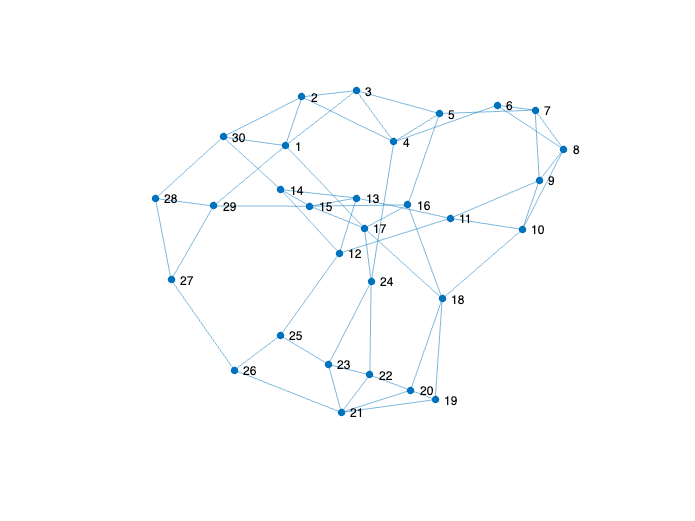

% Define parameters for the network of nonlinear oscillators
rng(115123,'v5normal')

N = 30;                     % Number of oscillators:
n = 2;                      % number of states per oscillator (agent)
Adj = SmallWorld(N,0.2,2);  % Adjoint matrix of a small world network
G = graph(Adj);             % Graph of adjoint matrix 
D = diag(sum(Adj,2));       % Degree matrix
Lp = D - Adj;               % Laplacian matrix

figure
plot(G)
set(gca,'Visible','off')


% Computing network density 
total_possible_edges = N*(N-1)*0.5; % Nc2
total_edges = size(G.Edges,1); 
network_density = total_edges/total_possible_edges;
fprintf('Network density = %.3f\n', network_density)

Network density = 0.138


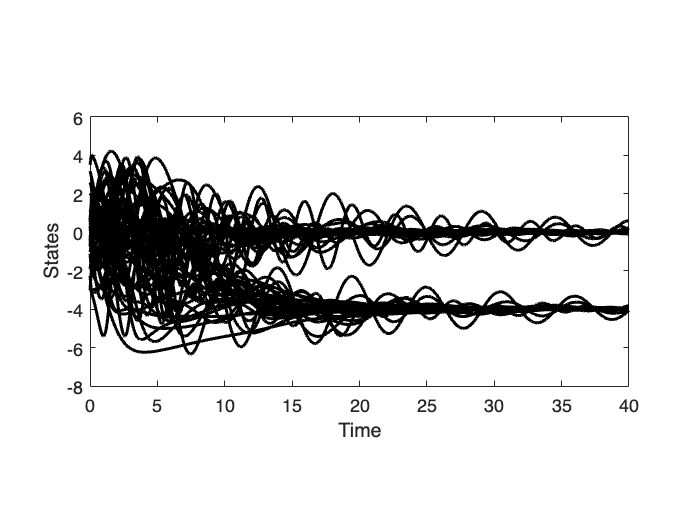

% Network of Van der Pol oscillators
Mu      = 0.15*rand(N,1); 
Omega   = diag(0.8*rand(N,1)); 

a       = -10;
b       = 10;
u_set   = (b-a).*rand(N,1)+a; % Control forcing  
simT    = 40;
simDT   = 2e-2;
simTime = 0:simDT:simT; 
num_of_data_points = floor(simT/simDT); 

x0      = 1.4*randn(n*N,1);

[ts,x_data] = ode45(@(t,x) Vdp_sys_c(t,x,u_set,Mu,Omega,Lp,N),simTime,x0);

num_time_points_control_applied = round(0.1/simDT); % Since the control is manually turned off inside the ode function 'Vdp_sys_c' after perturbation
U = [repmat(u_set,1,num_time_points_control_applied) zeros(N,length(ts)-1-num_time_points_control_applied)];

% Time-series plot 
figure
plot(ts,x_data,'LineWidth',2, 'color','k')
pbaspect([2,1,1])
xlabel('Time')
ylabel('States')

% Collect data to compute the Koopman matrix 
Xp = (x_data(1:end-1,:))';
Xf = (x_data(2:end,:))'; 
% Compute the required transformation matrices 
n_inputs = ones(N,1); 
[Tpp, Tfp, Tup, Rpp, Rfp, Rup] = compute_transformation_matrices_u(Adj, N, n, n_inputs);
LAMBDA = 0.012; % Regularization weight

Recursive Distributed DMD Computation 

which_initialization = 'initial_window'; % 'random' or 'initial_window'
if strcmp(which_initialization, 'random')
    T1 = 1; % make this value > 1 if you choose 'initial_window' under which_initialization
elseif strcmp(which_initialization,'initial_window')
    T1 = 8; % Choose 10 by default, however, user can chose their own value
end 
T2 = num_of_data_points - 1

T2 = 1999


% Closed loop system 
[A_RD_DMDu, B_RD_DMDu, learning_error] = RD_DMD_u(Xp, Xf, U, LAMBDA, N, Tfp, Rfp, T1, T2, n, which_initialization); 

% Stopping criterion parameters
threshold = 1e-3;
buffer_length = 5;
error = learning_error.A(2:end) - learning_error.A(1:end-1);

for time_iter = buffer_length+1:length(error)    
    if all(abs(error(time_iter-buffer_length:time_iter)) <= threshold)
        stop_iter = time_iter; 
        break; 
    end
end

stop_iter 

stop_iter = 434

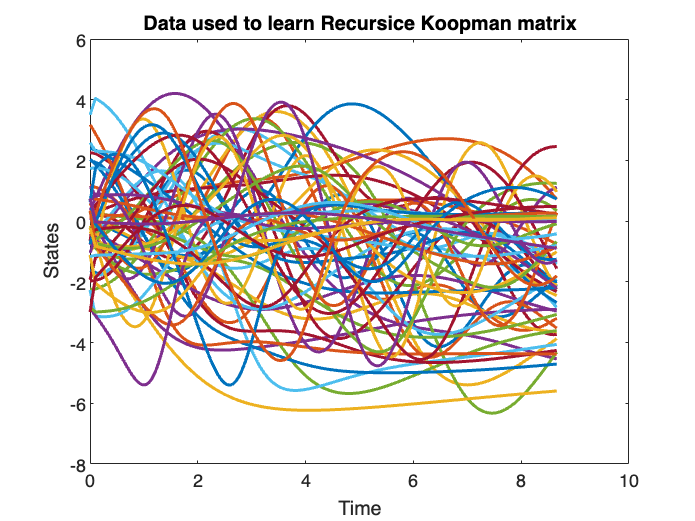


figure
plot(ts(1:stop_iter), x_data(1:stop_iter,:),'LineWidth',2)
xlabel('Time')
ylabel('States')
title('Data used to learn Recursice Koopman matrix')

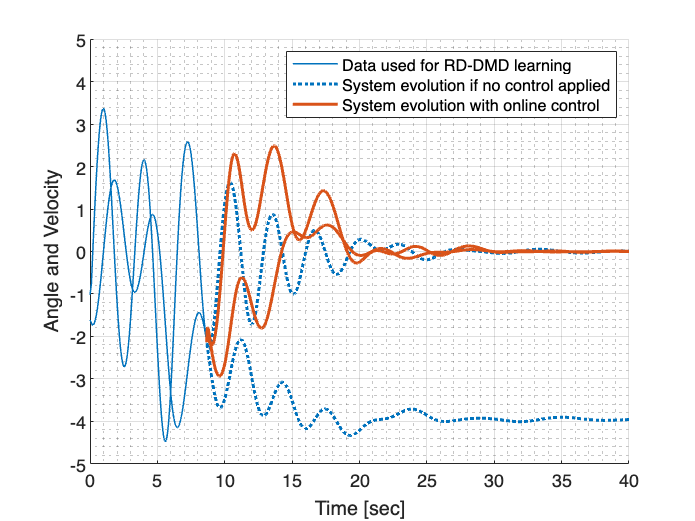


% Koopman matrix and input matrix when stopping criterion is met is 
% used for designing control 
Ao = A_RD_DMDu{stop_iter};
Bo = B_RD_DMDu{stop_iter};

% Control Design
q_gain = 1;
r_gain = 1; 
Q = q_gain*eye(2*N); 
R = r_gain*eye(N); 

K = dlqr(Ao,Bo,Q,R);
Ac = Ao - Bo*K;

% Number of time steps to simulate forward applying control and starting at
% where the learning ended 
num_time_steps = 2000;

Z = zeros(2*N,num_time_steps); 
control_effort = zeros(N,num_time_steps); 
Z(:,1:stop_iter) = (x_data(1:stop_iter,:))'; 
control_effort(:,1:stop_iter) = U(:,1:stop_iter);

for k = stop_iter:num_time_steps
    control_effort(:,k+1) = K*Z(:,k);
    Z(:,k+1) = Ac*Z(:,k); 
end

x_closed = Z; 

fig_comparison = figure; 
hold on
p1 = plot((0:stop_iter-1)*simDT, x_data(1:stop_iter,[1,N+1]), 'color', [0    0.4470    0.7410],'LineWidth',1);
p2 = plot((stop_iter:simT/simDT)*simDT, x_data(stop_iter+1:end,[1,N+1]), ':','color', [0    0.4470    0.7410],'LineWidth',2);
p3 = plot((stop_iter-1:num_time_steps)*simDT,x_closed([1,N+1],stop_iter:end),'color',[0.8500    0.3250    0.0980],'LineWidth',2,'HandleVisibility','off') ;
grid on 
grid minor 
legend([p1(1), p2(1), p3(1)],{'Data used for RD-DMD learning','System evolution if no control applied','System evolution with online control'})
xlabel('Time [sec]')
ylabel('Angle and Velocity')
ylim([-5,5])

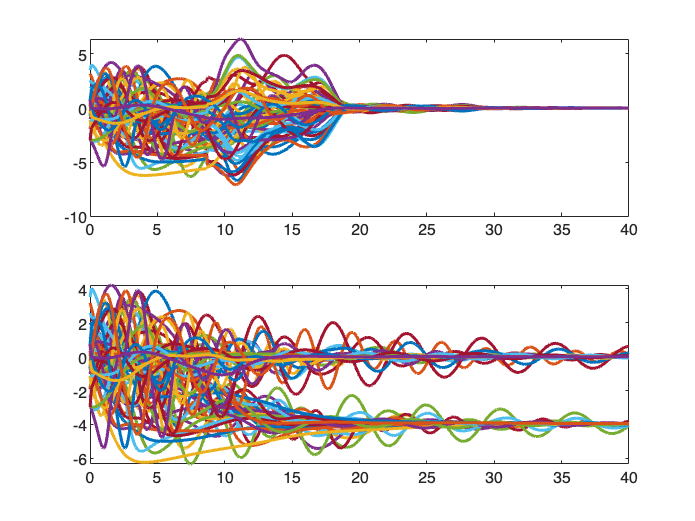


fig_closed_loop_states = figure; 
subplot(2,1,1)
plot((0:num_time_steps)*simDT,x_closed,'LineWidth',2); 
subplot(2,1,2)
plot(ts,x_data,'LineWidth',2)


if SavePlots 
    saveas(fig_comparison, sprintf('Figures/Closed_loop_open_loop_comparison_stop_iter%d_Q%.1f_R%.1f.jpg',stop_iter,q_gain,r_gain),'jpg')
    saveas(fig_closed_loop_states, sprintf('Figures/Closed_loop_states_stop_iter%d_Q%.1f_R%.1f.jpg',stop_iter,q_gain,r_gain),'jpg')    
end

toc

Elapsed time is 297.379870 seconds.


function xdot = Vdp_sys_c(t,x,u,Mu,Omega,L,N)
x1_dot = x(N+1:2*N); 
if t <= 0.1
    % Apply the control input to perturb the system and learn the system
    % behavior
    x2_dot = diag(Mu.*(1-x(1:N).^2))*x(N+1:2*N) + u - Omega*L*x(1:N); 
else
    x2_dot = diag(Mu.*(1-x(1:N).^2))*x(N+1:2*N)     - Omega*L*x(1:N);
end
xdot = [x1_dot; x2_dot];
end